% DADOS
fc1 = 44711

fc1 = 44711

fc2 = 117054

fc2 = 117054

R = 667

R = 667


% QUESTÃO 1
wc1 = 2*pi*fc1

wc1 = 2.8093e+05

wc2 = 2*pi*fc2

wc2 = 7.3547e+05

B = wc2 - wc1

B = 4.5454e+05

L = R/B % beta = R/L

L = 0.0015

w0 = sqrt(wc1*wc2)

w0 = 4.5455e+05

C = 1/(w0^2*L) % frequência central w0 = 1/sqrt(LC) 

C = 3.2983e-09


% QUESTÃO 2
f0 = w0/(2*pi)

f0 = 7.2344e+04

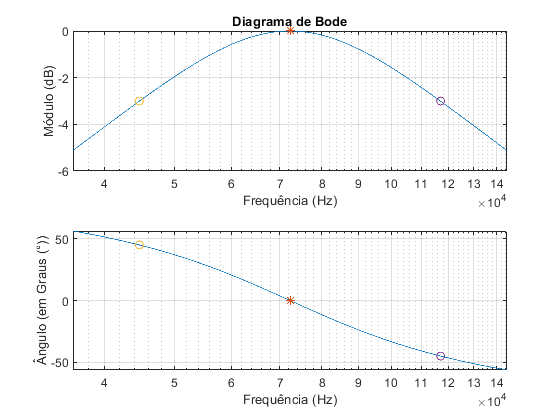


% QUESTÃO 3 - DIAGRAMA DE BODE

% PARÂMETROS INICIAIS
f = f0/2:10:f0*2;
w = 2*pi*f;

% PARÂMETROS DE CIRCUITO
Zc = 1./(1i*w*C);
Zl = 1i*w*L;

% FUNÇÃO DE TRANSFERÊNCIA
H = R./(Zc+Zl+R);

% DIAGRAMAS
figure(1)

subplot(211)
semilogx(f,20*log10(abs(H)),f0,0,'*',fc1,-3,'o',fc2,-3,'o')
grid on
xlabel('Frequência (Hz)')
ylabel('Módulo (dB)')
title('Diagrama de Bode')

subplot(212)
semilogx(f,rad2deg(angle(H)),f0,0,'*',fc1,45,'o',fc2,-45,'o')
grid on
xlabel('Frequência (Hz)')
ylabel('Ângulo (em Graus (°))')


% QUESTÃO 4 - FILTRO RC
% PASSA ALTA - FREQ INFERIOR
%wca = wc1
Ca = 1/(R*wc1)

Ca = 5.3368e-09


% PASSA BAIXA - FREQ SUPERIOR
%wcb = wc2
Cb = 1/(R*wc2)

Cb = 2.0385e-09


% PARÂMETROS DOS CIRCUITOS 
Zca = 1./(1i*2*pi*f*Ca)

Zca = 	1.0e+02 *

   0.0000 - 8.2446i   0.0000 - 8.2423i   0.0000 - 8.2400i   0.0000 - 8.2378i   0.0000 - 8.2355i   0.0000 - 8.2332i   0.0000 - 8.2310i   0.0000 - 8.2287i   0.0000 - 8.2264i   0.0000 - 8.2241i   0.0000 - 8.2219i   0.0000 - 8.2196i   0.0000 - 8.2173i   0.0000 - 8.2151i   0.0000 - 8.2128i   0.0000 - 8.2106i   0.0000 - 8.2083i   0.0000 - 8.2060i   0.0000 - 8.2038i   0.0000 - 8.2015i   0.0000 - 8.1993i   0.0000 - 8.1970i   0.0000 - 8.1948i   0.0000 - 8.1925i   0.0000 - 8.1903i   0.0000 - 8.1880i   0.0000 - 8.1858i   0.0000 - 8.1835i   0.0000 - 8.1813i   0.0000 - 8.1790i   0.0000 - 8.1768i   0.0000 - 8.1745i   0.0000 - 8.1723i   0.0000 - 8.1701i   0.0000 - 8.1678i   0.0000 - 8.1656i   0.0000 - 8.1634i   0.0000 - 8.1611i   0.0000 - 8.1589i   0.0000 - 8.1567i   0.0000 - 8.1544i   0.0000 - 8.1522i   0.0000 - 8.1500i   0.0000 - 8.1477i   0.0000 - 8.1455i   0.0000 - 8.1433i   0.0000 - 8.1411i   0.0000 - 8.1389i   0.0000 - 8.1366i   0.0000 - 8.1344i


Zcb = 1./(1i*2*pi*f*Cb)

Zcb = 	1.0e+03 *

   0.0000 - 2.1584i   0.0000 - 2.1579i   0.0000 - 2.1573i   0.0000 - 2.1567i   0.0000 - 2.1561i   0.0000 - 2.1555i   0.0000 - 2.1549i   0.0000 - 2.1543i   0.0000 - 2.1537i   0.0000 - 2.1531i   0.0000 - 2.1525i   0.0000 - 2.1519i   0.0000 - 2.1513i   0.0000 - 2.1507i   0.0000 - 2.1501i   0.0000 - 2.1495i   0.0000 - 2.1489i   0.0000 - 2.1484i   0.0000 - 2.1478i   0.0000 - 2.1472i   0.0000 - 2.1466i   0.0000 - 2.1460i   0.0000 - 2.1454i   0.0000 - 2.1448i   0.0000 - 2.1442i   0.0000 - 2.1436i   0.0000 - 2.1430i   0.0000 - 2.1425i   0.0000 - 2.1419i   0.0000 - 2.1413i   0.0000 - 2.1407i   0.0000 - 2.1401i   0.0000 - 2.1395i   0.0000 - 2.1389i   0.0000 - 2.1383i   0.0000 - 2.1378i   0.0000 - 2.1372i   0.0000 - 2.1366i   0.0000 - 2.1360i   0.0000 - 2.1354i   0.0000 - 2.1348i   0.0000 - 2.1343i   0.0000 - 2.1337i   0.0000 - 2.1331i   0.0000 - 2.1325i   0.0000 - 2.1319i   0.0000 - 2.1313i   0.0000 - 2.1308i   0.0000 - 2.1302i   0.0000 - 2.1296i



% FUNÇÕES DE TRANSFERÊNCIAS 
Ha = R./(R + Zca)

Ha =    0.3956 + 0.4890i   0.3957 + 0.4890i   0.3959 + 0.4890i   0.3960 + 0.4891i   0.3961 + 0.4891i   0.3962 + 0.4891i   0.3964 + 0.4891i   0.3965 + 0.4892i   0.3966 + 0.4892i   0.3968 + 0.4892i   0.3969 + 0.4893i   0.3970 + 0.4893i   0.3972 + 0.4893i   0.3973 + 0.4893i   0.3974 + 0.4894i   0.3976 + 0.4894i   0.3977 + 0.4894i   0.3978 + 0.4895i   0.3980 + 0.4895i   0.3981 + 0.4895i   0.3982 + 0.4895i   0.3984 + 0.4896i   0.3985 + 0.4896i   0.3986 + 0.4896i   0.3988 + 0.4896i   0.3989 + 0.4897i   0.3990 + 0.4897i   0.3992 + 0.4897i   0.3993 + 0.4898i   0.3994 + 0.4898i   0.3995 + 0.4898i   0.3997 + 0.4898i   0.3998 + 0.4899i   0.3999 + 0.4899i   0.4001 + 0.4899i   0.4002 + 0.4899i   0.4003 + 0.4900i   0.4005 + 0.4900i   0.4006 + 0.4900i   0.4007 + 0.4900i   0.4009 + 0.4901i   0.4010 + 0.4901i   0.4011 + 0.4901i   0.4013 + 0.4902i   0.4014 + 0.4902i   0.4015 + 0.4902i   0.4016 + 0.4902i   0.4018 + 0.4903i   0.4019 + 0.4903i   0.4020 + 0.4903i


Hb = Zcb./(R + Zcb)

Hb =    0.9128 - 0.2821i   0.9128 - 0.2821i   0.9127 - 0.2822i   0.9127 - 0.2823i   0.9127 - 0.2823i   0.9126 - 0.2824i   0.9126 - 0.2825i   0.9125 - 0.2825i   0.9125 - 0.2826i   0.9124 - 0.2827i   0.9124 - 0.2827i   0.9123 - 0.2828i   0.9123 - 0.2829i   0.9123 - 0.2829i   0.9122 - 0.2830i   0.9122 - 0.2830i   0.9121 - 0.2831i   0.9121 - 0.2832i   0.9120 - 0.2832i   0.9120 - 0.2833i   0.9120 - 0.2834i   0.9119 - 0.2834i   0.9119 - 0.2835i   0.9118 - 0.2836i   0.9118 - 0.2836i   0.9117 - 0.2837i   0.9117 - 0.2838i   0.9116 - 0.2838i   0.9116 - 0.2839i   0.9116 - 0.2839i   0.9115 - 0.2840i   0.9115 - 0.2841i   0.9114 - 0.2841i   0.9114 - 0.2842i   0.9113 - 0.2843i   0.9113 - 0.2843i   0.9112 - 0.2844i   0.9112 - 0.2845i   0.9112 - 0.2845i   0.9111 - 0.2846i   0.9111 - 0.2846i   0.9110 - 0.2847i   0.9110 - 0.2848i   0.9109 - 0.2848i   0.9109 - 0.2849i   0.9108 - 0.2850i   0.9108 - 0.2850i   0.9108 - 0.2851i   0.9107 - 0.2852i   0.9107 - 0.2852i



% A FUNÇÃO DE TRANSFERÊNCIA EM CASCATA É: 
% Hr = V0/V = Hb*Ha
Hr = Hb.*Ha

Hr =    0.4990 + 0.3348i   0.4992 + 0.3347i   0.4993 + 0.3346i   0.4995 + 0.3346i   0.4996 + 0.3345i   0.4998 + 0.3345i   0.4999 + 0.3344i   0.5000 + 0.3344i   0.5002 + 0.3343i   0.5003 + 0.3342i   0.5005 + 0.3342i   0.5006 + 0.3341i   0.5007 + 0.3341i   0.5009 + 0.3340i   0.5010 + 0.3339i   0.5012 + 0.3339i   0.5013 + 0.3338i   0.5015 + 0.3338i   0.5016 + 0.3337i   0.5017 + 0.3336i   0.5019 + 0.3336i   0.5020 + 0.3335i   0.5022 + 0.3335i   0.5023 + 0.3334i   0.5024 + 0.3333i   0.5026 + 0.3333i   0.5027 + 0.3332i   0.5029 + 0.3332i   0.5030 + 0.3331i   0.5032 + 0.3330i   0.5033 + 0.3330i   0.5034 + 0.3329i   0.5036 + 0.3329i   0.5037 + 0.3328i   0.5039 + 0.3327i   0.5040 + 0.3327i   0.5041 + 0.3326i   0.5043 + 0.3326i   0.5044 + 0.3325i   0.5046 + 0.3324i   0.5047 + 0.3324i   0.5048 + 0.3323i   0.5050 + 0.3323i   0.5051 + 0.3322i   0.5053 + 0.3321i   0.5054 + 0.3321i   0.5056 + 0.3320i   0.5057 + 0.3320i   0.5058 + 0.3319i   0.5060 + 0.3318i


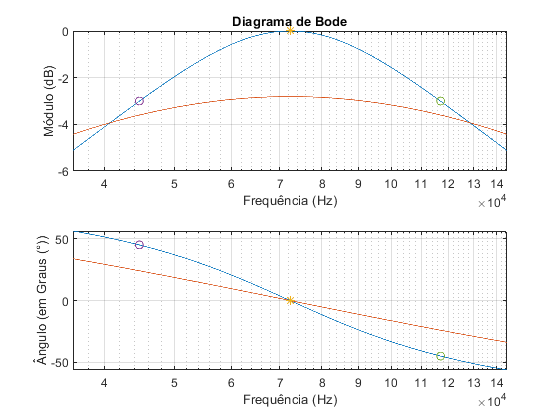


% DIAGRAMAS 
figure(2)
subplot(211)
semilogx(f,20*log10(abs(H)),f,20*log10(abs(Hr)),f0,0,'*',fc1,-3,'o',fc2,-3,'o')
grid on
xlabel('Frequência (Hz)')
ylabel('Módulo (dB)')
title('Diagrama de Bode')
subplot(212)
semilogx(f,rad2deg(angle(H)),f,rad2deg(angle(Hr)),f0,0,'*',fc1,45,'o',fc2,-45,'o')
grid on
xlabel('Frequência (Hz)')
ylabel('Ângulo (em Graus (°))')